# **Proposed Method**

clear
close all
clc

**Libraries**

addpath(genpath('.'));  % Auxiliar functions folder

**Parameters**

M = 32;
N = M;
L = 4;
S = 2;

**Data**

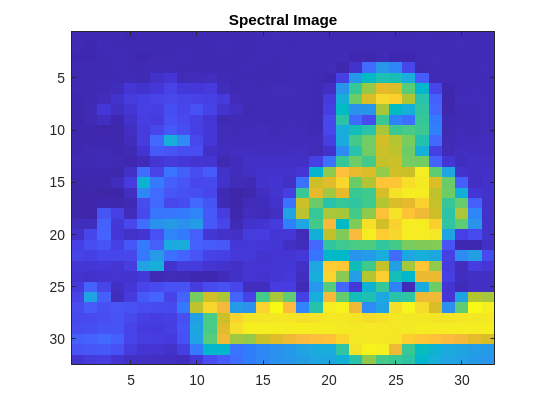

load('db_Lego_256');
d = hyperimg;
d = imresize(d(:, :, 1:size(d, 3) / L:end), [M N]);  % spatial and spectral resize

figure,
imagesc(squeeze(d(:, :, 1))), title('Spectral Image')

**Coded Apertures**

CAs = zeros(M, N, S); 
for j = 1:S
    CAs(:, :, j) = double(round(rand(M, N)));    % Coded aperture Random entries
end

**Sensing and computation of P and Q**

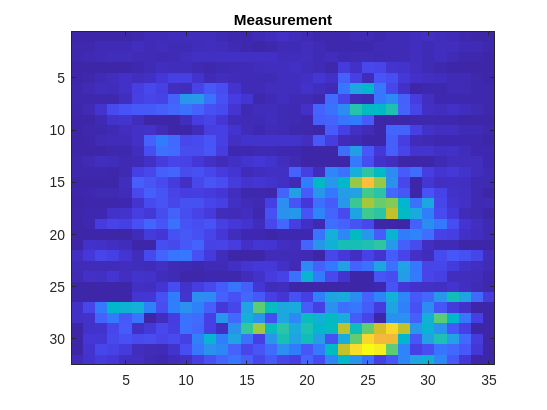

b = sensingH(d, CAs);
P = Computep(CAs, L);
Q = Computeq(CAs, L);

figure,
imagesc(squeeze(b(:, :, 1))), title('Measurement')

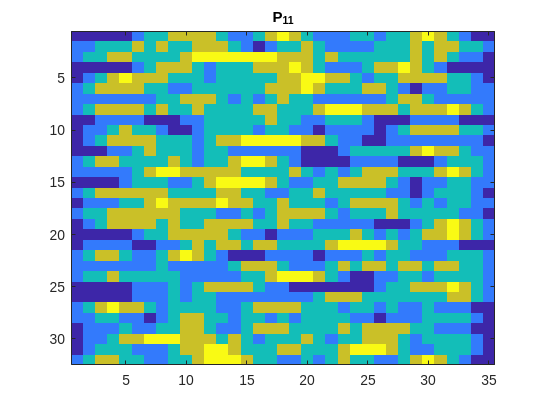


figure,
imagesc(squeeze(P(:, :, 1, 1))), title('P_{11}')

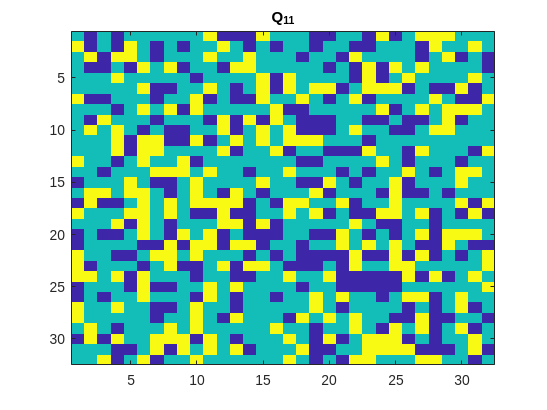


figure,
imagesc(squeeze(Q(:, :, 1, 1))), title('Q_{11}')

**H and Ht**

b = sensingH(d, CAs);
dnew = sensingHt(b, CAs);

**We now check formula **$\left(5\right)$** for **${\textrm{HH}}^* \mathbf{b}$ **or** $\textrm{Pb}$

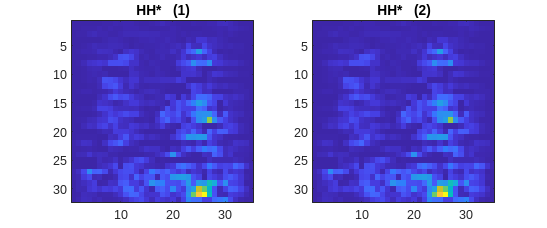

HHstarb1 = sensingH(sensingHt(b, CAs), CAs);
HHstarb2 = IMVM(P, b);

figure('Position', [0 0 600 250])
subplot(121), imagesc(squeeze(HHstarb1(:, :, 1))), title('HH*   (1)')
subplot(122), imagesc(squeeze(HHstarb2(:, :, 1))), title('HH*   (2)')


error = norm(HHstarb1(:) - HHstarb2(:));
disp(['HH* accuracy: ' num2str(error)])

HH* accuracy: 0


**We now check formula **$\left(8\right)$** for **${\mathbf{H}}^* \textrm{Hd}$ **or** $\textrm{Qd}$

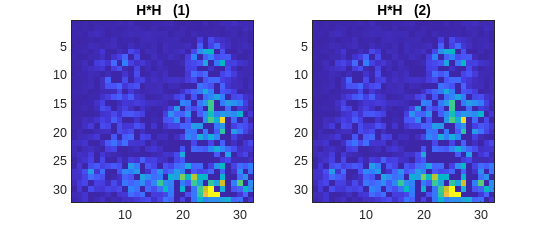

HstarHd1 = sensingHt(sensingH(d, CAs), CAs);
HstarHd2 = IMVMS(Q, d);

figure('Position', [0 0 600 250])
subplot(121), imagesc(squeeze(HstarHd1(:, :, 1))), title('H*H   (1)')
subplot(122), imagesc(squeeze(HstarHd2(:, :, 1))), title('H*H   (2)')


error = norm(HstarHd1(:) - HstarHd2(:));
disp(['H*H accuracy: ' num2str(error)])

H*H accuracy: 0


**We now check theorem **$4\ldotp 1$** for **${\left(\rho \mathbf{I}+{\textrm{HH}}^* \right)}^{-1}$ **or** ${\left(\rho \mathbf{I}+\mathbf{P}\right)}^{-1}$

**InvertedMeasurement:** ${\left(\rho \mathbf{I}+{\textrm{HH}}^* \right)}^{-1} \left(\rho \mathbf{I}+{\textrm{HH}}^* \right)\mathbf{b}=\mathbf{b}$

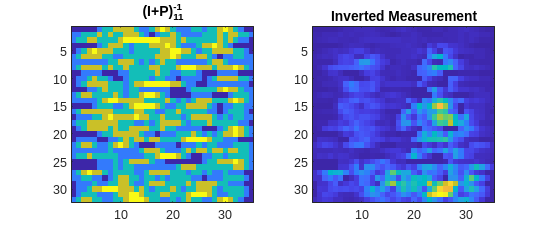

rho = 1;
[Pinv, rhoIP] = ComputePinv(P, rho);
InvertedMeasurement = IMVM(Pinv, rho * b + HHstarb1);

figure('Position', [0 0 600 250])
subplot(121), imagesc(squeeze(P(:,:,1,1))), title('(I+P)_{11}^{-1}')
subplot(122), imagesc(squeeze(InvertedMeasurement(:,:,1))), title('Inverted Measurement')


error = norm(b(:) - InvertedMeasurement(:));
disp(['Inversion accuracy: ' num2str(error)])

Inversion accuracy: 1.1379e-12


**We now check theorem **$4\ldotp 3$** for **${\left(\rho \mathbf{I}+{\mathbf{H}}^* \mathbf{H}\right)}^{-1}$ **or** ${\left(\rho \mathbf{I}+\mathbf{Q}\right)}^{-1}$

**InvertedImage:** ${\left(\rho \mathbf{I}+{\mathbf{H}}^* \mathbf{H}\right)}^{-1} \left(\rho \mathbf{I}+{\mathbf{H}}^* \mathbf{H}\right)\mathbf{d}=\mathbf{d}$

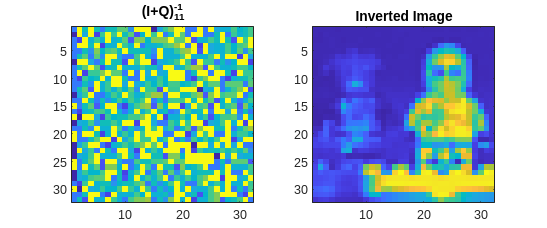

[Qinv, rhoIQ] = ComputeQinv(Q, rho);
InvertedImage = IMVMS(Qinv, rho * d + HstarHd1);

figure('Position', [0 0 600 250])
subplot(121), imagesc(squeeze(Qinv(:,:,1,1))), title('(I+Q)_{11}^{-1}')
subplot(122), imagesc(squeeze(InvertedImage(:,:,1))), title('Inverted Image')


error = norm(d(:) - InvertedImage(:));
disp(['Inversion accuracy: ' num2str(error)])

Inversion accuracy: 1.2668e-12


**Employing the Woodbury Lemma**

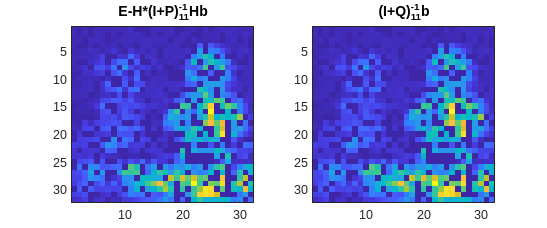

Y = sensingHt(b, CAs);
invHtH1 = Y - sensingHt(IMVM(Pinv, sensingH(Y, CAs)), CAs);
invHtH2 = IMVMS(Qinv, Y);

figure('Position', [0 0 600 250])
subplot(121), imagesc(squeeze(invHtH1(:,:,1,1))), title('E-H*(I+P)_{11}^{-1}Hb')
subplot(122), imagesc(squeeze(invHtH2(:,:,1))), title('(I+Q)_{11}^{-1}b')


error = norm(invHtH1(:) - invHtH2(:));
disp(['Inversion accuracy: ' num2str(error)])

Inversion accuracy: 2.523e-12
